C = cell(2,2); 

C{1,1} = rand(2,3); 
C{1,2} = rand(4,2); 
C{2,1} = rand(3,2); 
C{2,2} = rand(2,4); 

maxRows = max(cellfun(@(x) size(x, 1), C(:))); 
maxCols = max(cellfun(@(x) size(x, 2), C(:))); 

for i = 1:2
    for j = 1:2
        matrix = C{i,j};
        paddedMatrix = zeros(maxRows, maxCols);
        paddedMatrix(1:size(matrix,1), 1:size(matrix,2)) = matrix;  
        C{i,j} = paddedMatrix;  
    end
end

combined_matrix = cell2mat(C)

combined_matrix =     0.9049    0.4389    0.2581         0    0.5949    0.2217         0         0
    0.9797    0.1111    0.4087         0    0.2622    0.1174         0         0
         0         0         0         0    0.6028    0.2967         0         0
         0         0         0         0    0.7112    0.3188         0         0
    0.4242    0.2625         0         0    0.9289    0.4886    0.2373    0.9631
    0.5079    0.8010         0         0    0.7303    0.5785    0.4588    0.5468
    0.0855    0.0292         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


Sukurta matrica:


    0.1615    0.0942    0.6959    0.0336    0.5309
    0.1788    0.5985    0.6999    0.0688    0.6544
    0.4229    0.4709    0.6385    0.3196    0.4076



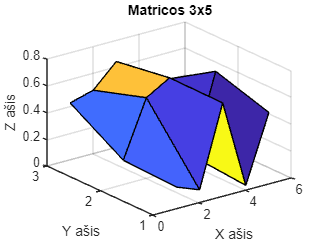

ivesti tie patys skaiciai. Darbas nutrauktas


clear all
while true
    m = input('Įveskite m (eilučių skaičius): ');
    n = input('Įveskite n (stulpelių skaičius): ');

    if m == n
        disp('Ivesti tie patys skaiciai. Darbas nutrauktas');
        break;
    end

    A = rand(m, n);

    disp('Sukurta matrica:');
    disp(A);

    figure;
    surf(A);
    title(['Matricos ' num2str(m) 'x' num2str(n)']);
    xlabel('X ašis');
    ylabel('Y ašis');
    zlabel('Z ašis');
end

fprintf('papildoma uzduotis')

papildoma uzduotis

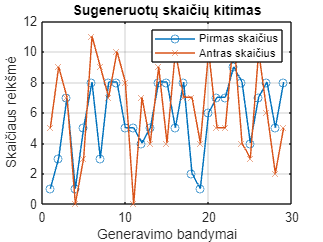

pirmi_skaiciai = [];
antri_skaiciai = [];

count = 0;

while count < 3
    pirmas = round(rand * 9); 
    antras = round(rand * 11);
    
    pirmi_skaiciai = [pirmi_skaiciai, pirmas];
    antri_skaiciai = [antri_skaiciai, antras];
    
    if pirmas > antras
        count = count + 1;
    else
        count = 0;
    end
end

figure;
plot(pirmi_skaiciai, '-o', 'DisplayName', 'Pirmas skaičius');
hold on;
plot(antri_skaiciai, '-x', 'DisplayName', 'Antras skaičius');
hold off;

title('Sugeneruotų skaičių kitimas');
xlabel('Generavimo bandymai');
ylabel('Skaičiaus reikšmė');
legend show;
grid on;